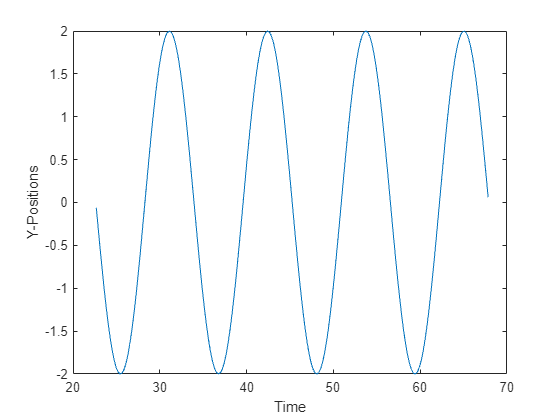

%FO8
clc
clear all
close all
% wpts = [1 4 4 3 -2 0; 0 1 2 4 3 1];
inf_wpts_zy = [0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0; 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0]; 
inf_wpts_xy = [0 2 4 6 8 6 4 2 0 2 4 6 8 6 4 2 0 2 4 6 8 6 4 2 0 2 4 6 8 6 4 2 0; 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0];
% tpts = 0:5;
inf_tpts = 0:sqrt(8):sqrt(8)*8*4;

numsamples = 100*4;

[inf_xy,inf_xyd,inf_xydd,inf_xyddd,inf_xydddd,inf_xypp,inf_xytimepoints,inf_xytsamples] = minsnappolytraj(inf_wpts_xy,inf_tpts,numsamples);
[inf_zy,inf_zyd,inf_zydd,inf_zyddd,inf_zydddd,inf_zypp,inf_zytimepoints,inf_zytsamples] = minsnappolytraj(inf_wpts_zy,inf_tpts,numsamples);

inf_final_pose = zeros(2,200);
inf_final_vel = zeros(2,200);
inf_final_acc = zeros(2,200);
inf_final_jerk = zeros(2,200);
inf_final_snap = zeros(2,200);

inf_final_z_pose = inf_zy(1,101:300);
inf_final_z_vel = inf_zyd(1,101:300);
inf_final_z_acc = inf_zydd(1,101:300);
inf_final_z_jerk = inf_zyddd(1,101:300);
inf_final_z_snap = inf_zydddd(1,101:300);

for v = 1:2
    inf_final_pose(v,:) = inf_xy(v,101:300);
    inf_final_vel(v,:) = inf_xyd(v,101:300);
    inf_final_acc(v,:) = inf_xydd(v,101:300);
    inf_final_jerk(v,:) = inf_xyddd(v,101:300);
    inf_final_snap(v,:) = inf_xydddd(v,101:300);
end

%plot(tsamples,q);
%plot(tsamples,q(1,:)) % matlab rows and cols start with 1 and not 0 unlike
%python
%disp (timepoints); % produces the m x n which is the rows and columns respectively of the matrix 

%hold on
%plot(timepoints,wpts,'x')

figure(1)
% subplot(3,1,1) 
plot(inf_zytsamples(1,101:300), inf_final_pose(2,:))
xlabel('Time');
ylabel('Y-Positions');

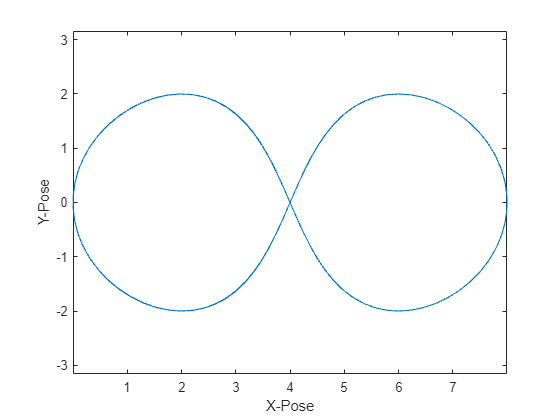

% subplot(3,1,2) 
plot(inf_final_pose(1,:), inf_final_pose(2,:))
xlabel('X-Pose')
ylabel('Y-Pose')
axis equal

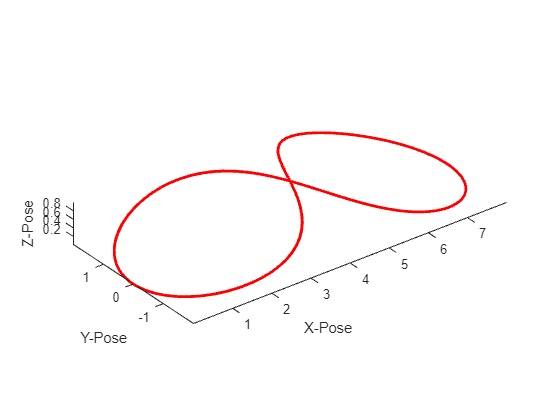

% grid
% 
% subplot(3,1,3)

plot3(inf_final_pose(1,:), inf_final_pose(2,:), inf_final_z_pose, "red",'LineWidth',2);
xlabel('X-Pose')
ylabel('Y-Pose')
zlabel('Z-Pose')
axis equal

% %legend('X-positions','Y-positions')

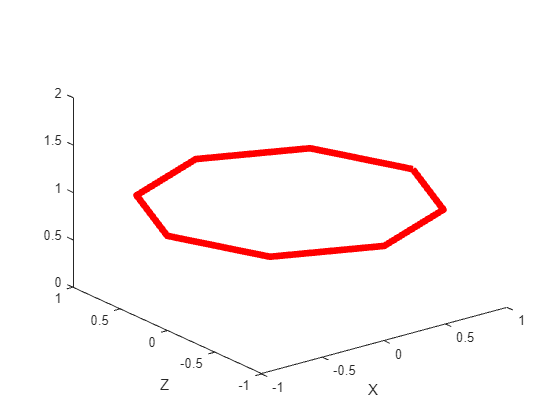

%CIRCLE
clc
clear all
close all
r=1;
[c,x,y] = circle(0,0,r);

disp (size(x));

     1     9



disp ((x));

    1.0000    0.7071    0.0000   -0.7071   -1.0000   -0.7071   -0.0000    0.7071    1.0000



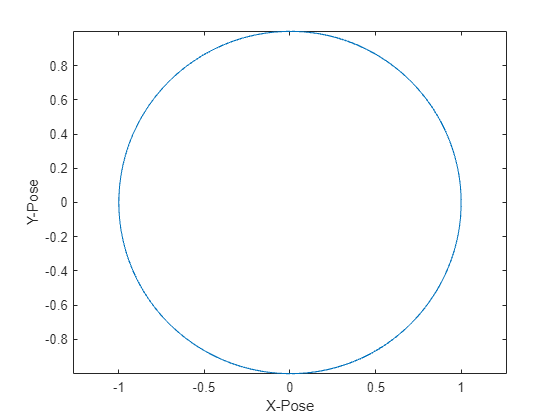



% wpts = [1 4 4 3 -2 0; 0 1 2 4 3 1];
%wpts_zy = [0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0; 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0]; 
circle_wpts_xy = [x x(:,2:end) x(:,2:end) x(:,2:end); y y(:,2:end) y(:,2:end) y(:,2:end)];
% tpts = 0:5;
circle_tpts = 0:pi/50:(pi/50)*8*4; 

numsamples = 100*4;

[circle_xy,circle_xyd,circle_xydd,circle_xyddd,circle_xydddd,circle_xypp,circle_xytimepoints,circle_xytsamples] = minsnappolytraj(circle_wpts_xy,circle_tpts,numsamples);
%[zy,zyd,zydd,zyddd,zydddd,zypp,zytimepoints,zytsamples] = minsnappolytraj(wpts_zy,tpts,numsamples);

circle_final_pose = zeros(2,200);
circle_final_vel = zeros(2,200);
circle_final_acc = zeros(2,200);
circle_final_jerk = zeros(2,200);
circle_final_snap = zeros(2,200);

% final_z_pose = zy(1,101:300);
% final_z_vel = zyd(1,101:300);
% final_z_acc = zydd(1,101:300);
% final_z_jerk = zyddd(1,101:300);
% final_z_snap = zydddd(1,101:300);

for v = 1:2
    circle_final_pose(v,:) = circle_xy(v,101:300);
    circle_final_vel(v,:) = circle_xyd(v,101:300);
    circle_final_acc(v,:) = circle_xydd(v,101:300);
    circle_final_jerk(v,:) = circle_xyddd(v,101:300);
    circle_final_snap(v,:) = circle_xydddd(v,101:300);
end

%plot(tsamples,q);
%plot(tsamples,q(1,:)) % matlab rows and cols start with 1 and not 0 unlike
%python
%disp (timepoints); % produces the m x n which is the rows and columns respectively of the matrix 

%hold on
%plot(timepoints,wpts,'x')

figure(1)
% subplot(3,1,1) 
% plot(zytsamples(1,101:300), final_pose(2,:))
% xlabel('Time');
% ylabel('Y-Positions');
% subplot(3,1,2) 
plot(circle_final_pose(1,:), circle_final_pose(2,:))
xlabel('X-Pose')
ylabel('Y-Pose')
axis equal

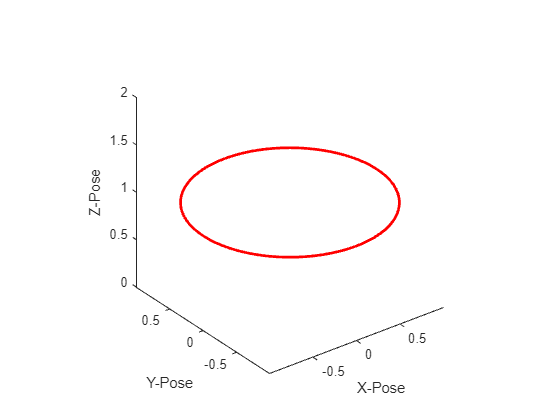

% grid
% 
% subplot(3,1,3)
z = ones([size(circle_final_pose(1,:))]);
plot3(circle_final_pose(1,:), circle_final_pose(2,:), z, "red",'LineWidth',2);
xlabel('X-Pose')
ylabel('Y-Pose')
zlabel('Z-Pose')
axis equal

% %legend('X-positions','Y-positions')


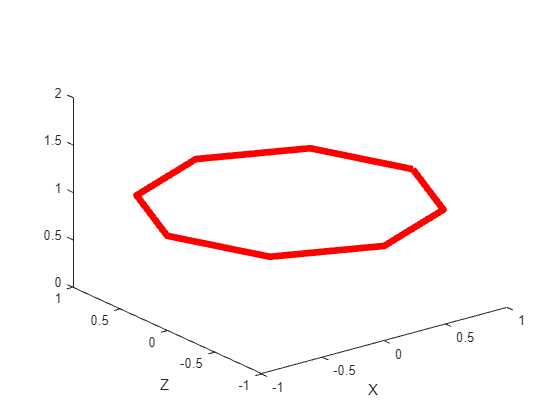

clc
clear all
close all
[c,x,y] = circle(0,0,1);

disp (size(x));

     1     9




% Specify waypoints, times of arrival, and sampling rate. 
wp = [0 0 0; 2 -2 0; 4 0 0; 6 2 0; 8 0 0; 6 -2 0; 4 0 0; 2 2 0; 0 0 0];
toa = sqrt(8)*(0:size(wp,1)-1).'

toa =          0
    2.8284
    5.6569
    8.4853
   11.3137
   14.1421
   16.9706
   19.7990
   22.6274


vel = [0 0 0; 1 1 0; 1 1 0; 1 1 0; 1 1 0; 1 1 0; 1 1 0; 1 1 0; 0 0 0];
Fs = 100; % resolution

% Create trajectory. 
traj = waypointTrajectory(wp, toa, SampleRate=Fs, ReferenceFrame='ENU')

traj =   waypointTrajectory with properties:

         SampleRate: 100
    SamplesPerFrame: 1
          Waypoints: [9×3 double]
      TimeOfArrival: [9×1 double]
         Velocities: [9×3 double]
             Course: [9×1 double]
        GroundSpeed: [9×1 double]
          ClimbRate: [9×1 double]
        Orientation: [9×1 quaternion]
          AutoPitch: 0
           AutoBank: 0
     ReferenceFrame: 'ENU'


disp (traj.Velocities);

    0.0000   -1.1787         0
    1.0758    0.1495         0
    0.4682    0.9317         0
    1.0758    0.1495         0
    0.0000   -1.1333         0
   -1.0758    0.1495         0
   -0.4682    0.9317         0
   -1.0758    0.1495         0
    0.0000   -1.1787         0



% Get position.
t = 0:1/Fs:traj.TimeOfArrival(end);
pos = lookupPose(traj, t);
size(pos)

ans =         2263           3


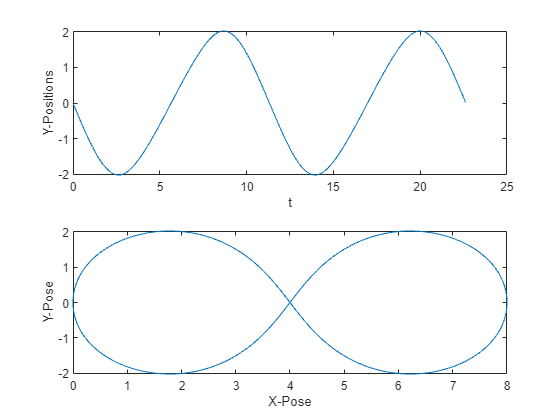


figure(1)
subplot(2,1,1) 
plot(t,pos(:,2))
xlabel('t');
ylabel('Y-Positions');
subplot(2,1,2) 
plot(pos(:,1),pos(:,2))
xlabel('X-Pose')
ylabel('Y-Pose')

function [overall,xunit,yunit] = circle(x,y,r)
% hold on
x_origin = x;
y_origin = y;
radius = r;
%th = 0:pi/50:2*pi; % 100 pts
th = 0:pi/4:2*pi; % 8 pts
xunit = radius * cos(th) + x_origin;
yunit = radius * sin(th) + y_origin;
z = ones([size(xunit)]);
overall = plot3(xunit, yunit, z, "red",'LineWidth',5);
xlabel('X')
ylabel('Y')
ylabel('Z')
%axis equal
% hold off
end


